# Morphing LED spectra for light source calibration

2024-02-24 Julius Muschaweck

*Note: This is an early draft to show the concept before I wrap up everything in a set of canned routines*

Typically, we drive an LED with a constant current source, i.e., a given forward current $I_f$. Even with pulse width modulation, it is the instantaneous current that is responsible for the instantaneous light output. For good control, we also should know the LED's junction temperature $T_j$. This is hard to measure, but can be well approximated by a temperature sensor like an NTC resistor close to the LED on the printed circuit board, combined with a simple thermal model of the LED (the thermal resistance from junction to solder point is typically given in the data sheet).

For high quality light sources, e.g. tunable white with several multi color LEDs in shop lighting, we would like to predict the spectral output for any drive current and junction temperature. To calibrate this input, we can acquire the necessary input information by measuring the spectral output for a range of controlled current and temperature inputs, e.g. on a rectangular grid of all combinations of $I_f = [20, 50, 100, 200, 400, 1000] $ mA and $T_j = [25, 50, 75, 100, 125]$ °C. To calculate the spectral output at any current and temperature, based on these measurements, we need to "interpolate" between the measured spectra. 

Simple linear interpolation fails abysmally: We want the LED spectrum to "move" from one peak wavelength to the next, while slowly changing, "morphing" its shape. In other words, we want this (a contrived visualization, not necessarily a true interpolation):

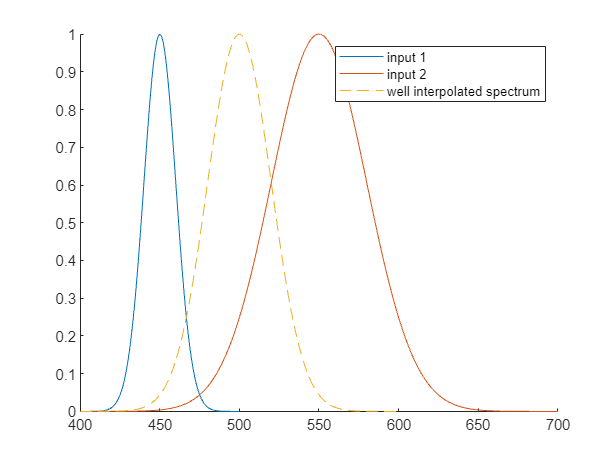

figure();hold on;
p1 = GaussSpectrum(400:500,450,10);
PlotSpectrum(p1);
p2 = GaussSpectrum(400:700,550,30);
PlotSpectrum(p2);
PlotSpectrum(GaussSpectrum(400:600,500,20),'--');
legend({'input 1','input 2', 'well interpolated spectrum'})

not this two-humped camel: 

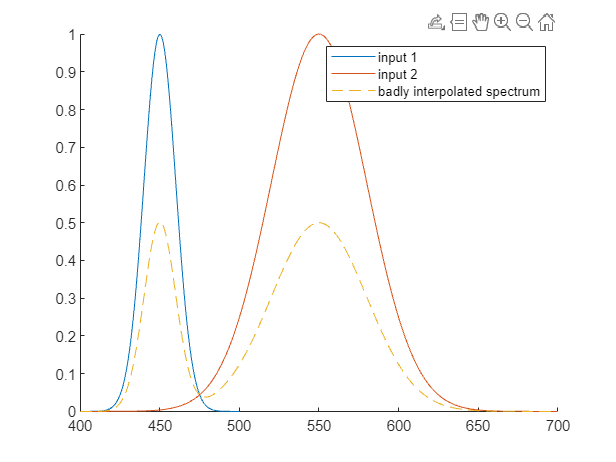

figure();hold on;
PlotSpectrum(p1);
PlotSpectrum(p2);
PlotSpectrum(AddWeightedSpectra({p1,p2},[0.5, 0.5]),'--');
legend({'input 1','input 2', 'badly interpolated spectrum'})

One approach would be that of moments: We could interpret a spectrum as a probability density function, and compute a certain number of its moments. The desired spectrum would be obtained by interpolating moments, and recreate the distribution from the interpolated moments. While this may work well for simple distributions like single color LEDs, a large, and a priori unknown, number of moments is necessary to reproduce the spectral shape of white LEDs. Moreover, even the base spectra themselves would not be fully reproduced, but only approximated. 

Here, we propose a different approach, based on optimal mass transport theory. It is known from optimal mass transport theory that the least cost approach to  move a 1D heap of sand to another 1D heap of sand of same mass is the following. We first scale total mass to one, making the two heaps of sand 1D probability densities $f_1(\lambda)$ and $f_2(\lambda)$. Then, we integrate them to obtain cumulative probability functions


$$F_1(\lambda) = \int_{\lambda_0}^\lambda f_1(\lambda')\, \mathrm d \lambda', \ \mathbb R\rightarrow [0;1]$$


and likewise for $F_2$.

The range of the $F$'s is [0;1]. As long as the  $f$'s are strictly positive in their simply connected domain (which spectra typically are, or can be made to be with negligible error), the $F$'s are strictly monotonously ascending and cover the full range of [0;1]. They can therefore be inverted:


$$G_{1,2} = F_{1,2}^{-1}: [0;1]\rightarrow \mathbb R$$


All $G$'s now live on the same domain, and are strictly ascending. Interpolation is now achieved by simply creating thir weighted sum:

$G(x) = w_1G_1(x) + (1-w_1)G_2(x)$.

with $w_1\in[0;1]$. The weighted sum of strictly ascending functions with positive weights is strictly ascending, and therefore invertible: 


$$F = G^{-1}: \mathrm{Im}(G) \rightarrow [0;1]$$


The image of $G$ will be our final range of wavelengths of the interpolated spectrum. 

Now, our interpolated heap of sand is the derivative:

$f(\lambda) = F'(\lambda)$.

This interpolated probability density is to be scaled by a constant factor to achieve the correct total power in the actual output spectrum. This interpolated output power is simply the weighted addition of the input powers.

A few remarks for using tabulated LED spectra as input: Some technicalities must be taken care of to make things work well. 

- Wavelength values must be strictly ascending. 

- Negative and zero spectrum values must be set to a small positive number, say, 0.00001 times peak. 

- End points of the cumulative distributions $F$ must be set to 0 and 1 to remove roundoff errors. 

- The inverse cumulative distribution tables for the $G$'s must be "interweaved" using e.g. simple linear interpolation such that their domain arrays are the same, making subsequent weighted addition easy. This is done by taking all values in the domain arrays, sorting them, removing duplicates, and then linearly interpolating the value arrays on the new full domain array.

- For the final differentiation $f(\lambda) = F'(\lambda)$, we should not apply finite differences. Instead, we should use the inverse function differentiation rule: $F'(\lambda) = \frac{1}{G'(x)} = \frac{1}{\sum G_i'(x)} = \frac{1}{\sum \frac{1}{F_i'(G_i(x))}} = \frac{1}{\sum \frac{1}{f_i(G_i(x))}}$

- This requires a similar linear interpolation of all $f_i$ for the wavelength array obtained by applying $G_i$ to the full range of interweaved $x$ values, but it's simple and foolproof, as long as the input $f_i$ are not negligibly small or zero (this is why we required that the original input spectrum values must all be >= a small positive number). And it avoids all the discretization issues with finite differencing.

In this example, I'm using only two input spectra. However, the approach can be extended in a natural way to more input spectra. For *n *input spectra, we need *n *weights with $\sum w_i = 1, w_i \in [0;1]$ and everything else just falls into place. A most useful case will be to interpolate spectra in a rectangular $I,T$ grid, using the four spectra at the corners as input.

Let's look at an example. Several routines come from my spectrum library, freely available at [https://github.com/JuliusMuschaweck/JMO_Spectrum](https://github.com/JuliusMuschaweck/JMO_Spectrum)

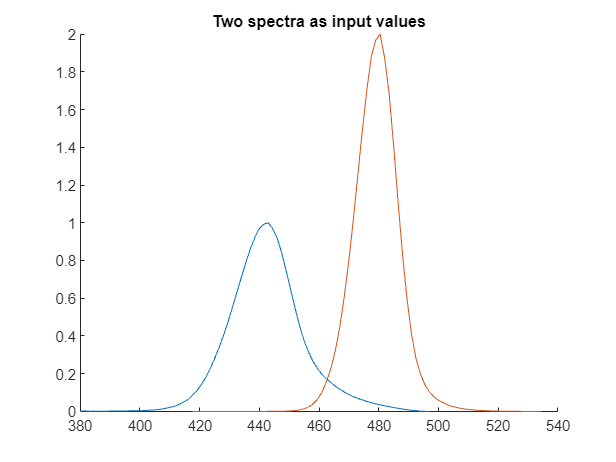


clear;

minval = 0.00001; % no zero spectrum values

% a typical blue spectrum;
blue1 = ReadLightToolsSpectrumFile("blue.sre"); % from my spectrum library
blue1.val( blue1.val < minval * max(blue1.val) ) = minval * max(blue1.val);

% a shifted blue spectrum
tmp = ShiftToLdom(blue1, 480); % from my spectrum library
tmp.val = tmp.val .^ 2; % some nonlinear transformation to give it a different shape
blue2 = ScaleSpectrum(tmp,'mode','multiply','value',2); % and a different peak
blue2.val( blue2.val < minval ) = minval;

% let's take a look
figure()
hold on;
PlotSpectrum(blue1); % from my spectrum library
PlotSpectrum(blue2);
title("Two spectra as input values");

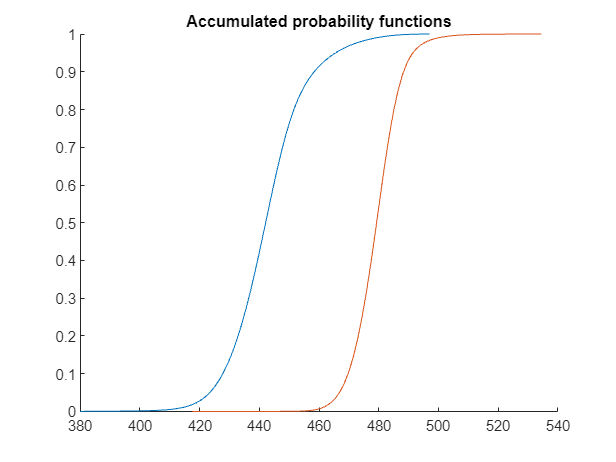


% for power scaling
phi1 = IntegrateSpectrum(blue1); % from my spectrum library
phi2 = IntegrateSpectrum(blue2);

% the cumulative distributions
F1 = F(blue1,phi1); % local function, see below
F2 = F(blue2,phi2);
figure(); hold on;
PlotSpectrum(F1);
PlotSpectrum(F2);
title("Accumulated probability functions");

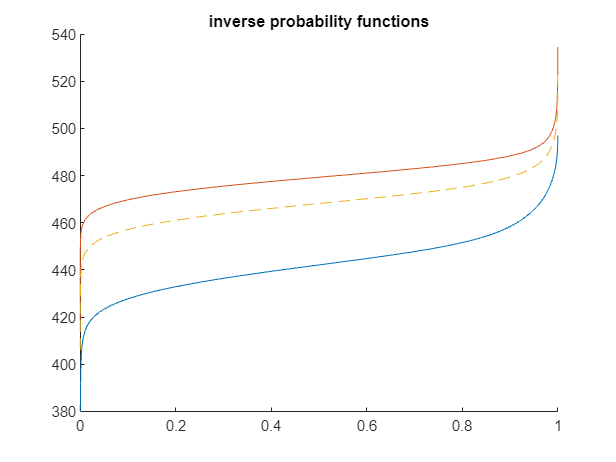


% the inverse distributions
G1 = G(F1);% local function, see below
G2 = G(F2);
% which we now resample to the interweaved 
x = unique(sort(cat(1, G1.lam, G2.lam)));
G1 = ResampleSpectrum(G1, x); % from my spectrum library
G2 = ResampleSpectrum(G2, x);
myG.lam = x;

% the weights
% change w1 to anything in [0;1] to see how the interpolated spectrum behaves
w1 = 0.3;
w2 = 1 - w1;
% and the weighted sum of the inverse probability functions
myG.val = w1 * G1. val + w2 * G2.val;

figure(); hold on;
PlotSpectrum(G1);
PlotSpectrum(G2);
PlotSpectrum(myG,'--');
title("inverse probability functions")

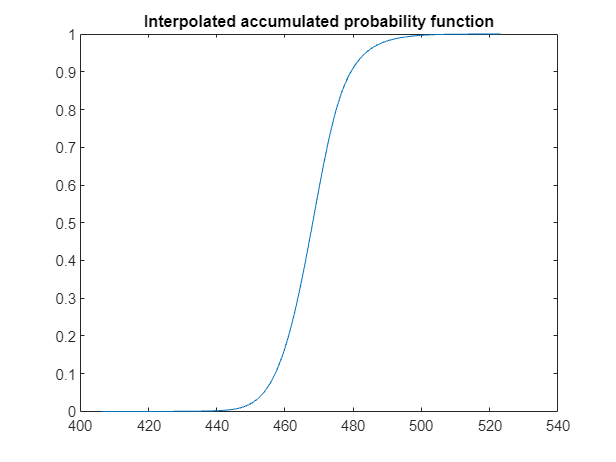


myF.lam = myG.val;
myF.val = myG.lam;
myF.val(1) = 0;

figure();
PlotSpectrum(myF);
title("Interpolated accumulated probability function")


f1 = LinInterpol(blue1.lam, blue1.val, G1.val); % from my spectrum library,
f2 = LinInterpol(blue2.lam, blue2.val, G2.val); % equivalent to interp1 with linear interpolation

myf = 1 ./ (w1 ./ f1 + w2 ./ f2);
myscale = trapz(myG.val,myf)

myscale = 30.7935

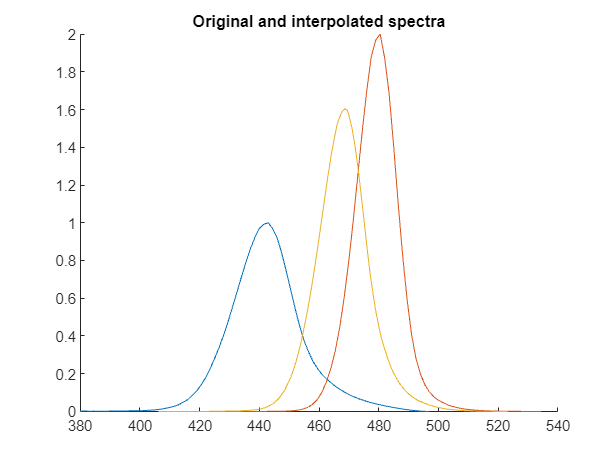

myphi = w1 * phi1 + w2 * phi2;

myblue.lam = myG.val;
myblue.val = myf / myscale * myphi;

figure();
hold on;
PlotSpectrum(blue1);
PlotSpectrum(blue2);
PlotSpectrum(myblue);
title("Original and interpolated spectra")

function rv = F(spec, phi)
    rv.lam = spec.lam;
    rv.val = cumtrapz(spec.lam, spec.val) / phi;
    rv.val(end) = 1; % 
end

function rv = G(rhs)
    rv.lam = rhs.val;
    rv.val = rhs.lam;
    rv.lam(1) = eps; % hack to make it a valid "spectrum" with all lam > 0;
end